clear;
load data2.mat;
data = [X,y];


%Open the app and select the predictor and response variables
%In the MATLAB Apps tab, select the 'Classification Learner' from the 'Machine Learning' section 
%Select 'New Session -> From Workspace' to start a new interactive session.
%Under 'Data Set Variable', select 'data'.
%Under 'Validation', select 'Cross-Validation' and use the slider to select 10 folds 
%Click the 'Start Session' button. 

%select and train the model
%In the model list, the default model is 'Fine Tree'. Expand the model list and select 'Fine Gaussian SVM' from the 'Support Vector Machines' list.
%Select 'Train' to train the model. Note that the data is automatically normalized before training.



%Export the model to the workspace and extract the model variable
%Select 'Export Model -> Export Model'.
%Select the default output variable name ('trainedModel') and click 'OK'.

gaussSVMmdl = trainedModel.ClassificationSVM

gaussSVMmdl =   ClassificationSVM
           PredictorNames: {'column_1'  'column_2'}
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [0 1]
           ScoreTransform: 'none'
          NumObservations: 863
                    Alpha: [177×1 double]
                     Bias: 0.2140
         KernelParameters: [1×1 struct]
                       Mu: [0.5034 0.6943]
                    Sigma: [0.2550 0.1589]
           BoxConstraints: [863×1 double]
          ConvergenceInfo: [1×1 struct]
          IsSupportVector: [863×1 logical]
                   Solver: 'SMO'


  Properties, Methods





figure; hold on;
x1 = linspace(min(X(:,1)),max(X(:,1)));
x2 = linspace(min(X(:,2)),max(X(:,2)));
[Xgrid,Ygrid] = meshgrid(x1,x2);
q = predict(gaussSVMmdl, [Xgrid(:), Ygrid(:)]);


w =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


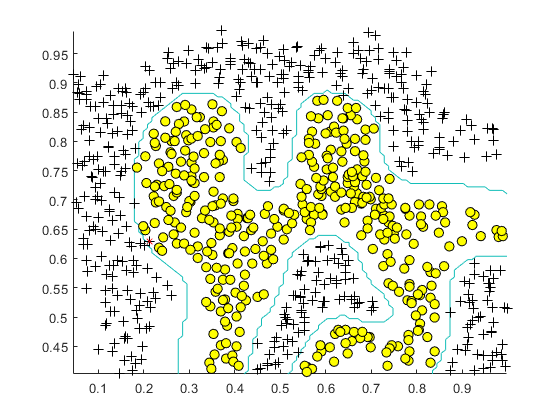

Z=reshape(predict(gaussSVMmdl,[Xgrid(:),Ygrid(:)]), size(Xgrid));
contour(Xgrid,Ygrid,Z,'Levels',1); 
plot(X(y==1,1),X(y==1,2),'k+','MarkerSize',7);
plot(X(~y,1),X(~y,2),'ko','MarkerFaceColor','y','MarkerSize',7); 
misclassidx = y~=predict(gaussSVMmdl,X);
plot(X(misclassidx,1),X(misclassidx,2),'rx')

hold off;
    


    
 





indices =

  0×1 empty double column vector



Element not found!
